clc
clear all;
close all;

imPath = 'body_part_detection/Datasets';
dataPath = imageDatastore(imPath, 'IncludeSubfolders', true, 'LabelSource', 'foldernames');
dataNum = countEachLabel(dataPath);

% Select the minimum no of imgs from folders
min_dataNum = min(dataNum{:, 2});

% Consider images of all folders equal to minimum number
min_Data = splitEachLabel(dataPath, min_dataNum, 'randomized');

% See the result of the split
countEachLabel(min_Data)

ans = 4×2 table
    Label     Count
    ______    _____

    Foot       242 
    Hand       242 
    Mouth      242 
    Normal     242 


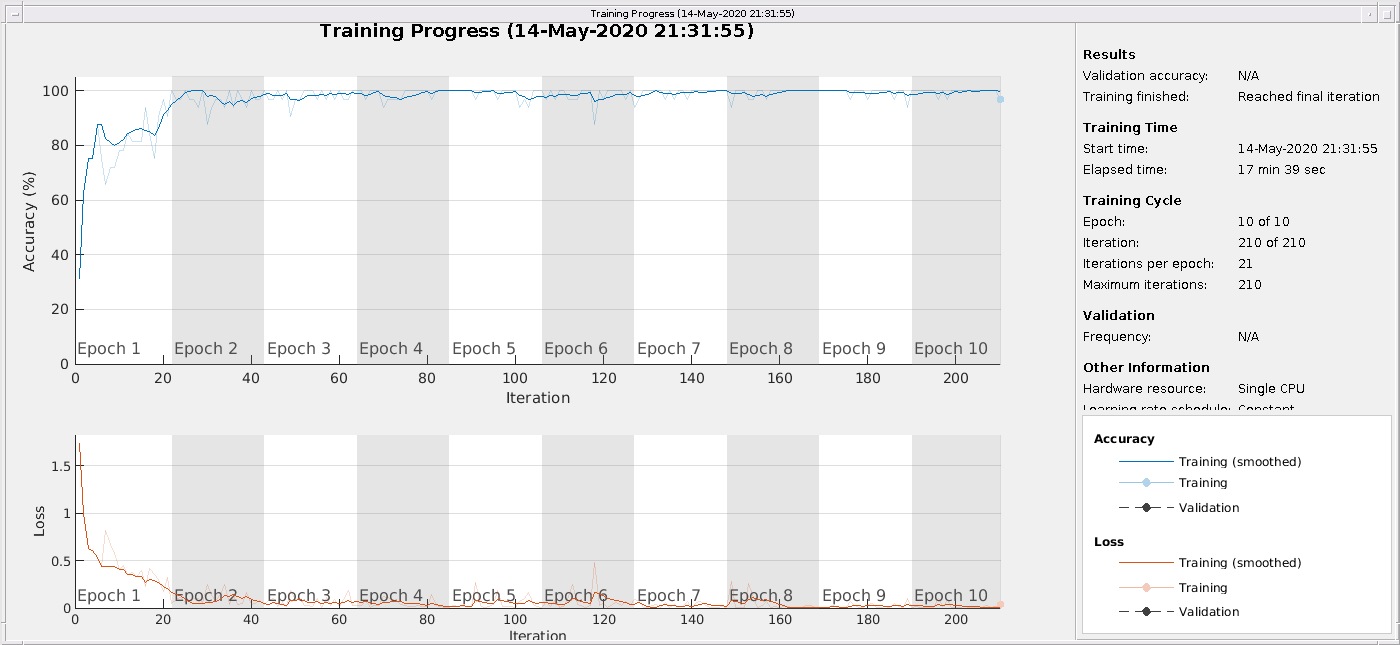


% Load Network
net = resnet50();
lgraph = layerGraph(net);
% clear net;

% Split 70% for training and rest for testing
[trainSet, validationSet] = splitEachLabel(min_Data, 0.7, 'randomized');

% % Get the number of classes
% numClasses = numel(trainSet.Labels);

% New Learnable Layer
newLearnableLayer = fullyConnectedLayer(4, 'Name','new_fc', ...
    'WeightLearnRateFactor',10, ...
    'BiasLearnRateFactor',10);
    
% Replacing the last layers with new layers
lgraph = replaceLayer(lgraph,'fc1000',newLearnableLayer);
newsoftmaxLayer = softmaxLayer('Name','new_softmax');
lgraph = replaceLayer(lgraph,'fc1000_softmax',newsoftmaxLayer);
newClassLayer = classificationLayer('Name','new_classoutput');
lgraph = replaceLayer(lgraph,'ClassificationLayer_fc1000',newClassLayer);

% Training Options, we choose a small mini-batch size due to limited images 
options = trainingOptions('adam',...
    'MaxEpochs',10,'MiniBatchSize',32,...
    'Shuffle','every-epoch', ...
    'InitialLearnRate',1e-4, ...
    'Verbose',false, ...
    'Plots','training-progress');

% Data Augumentation
augmenter = imageDataAugmenter( ...
    'RandRotation',[-5 5],'RandXReflection',1,...
    'RandYReflection',1,'RandXShear',[-0.05 0.05],'RandYShear',[-0.05 0.05]);

% Input image size
imgSize = net.Layers(1).InputSize;

% Resizing all training images to [224 224] for ResNet architecture
augTrainSet = augmentedImageDatastore(imgSize, trainSet, 'ColorPreprocessing', 'gray2rgb', 'DataAugmentation', augmenter);

% Training
classifier = trainNetwork(augTrainSet,lgraph,options);


% Resizing all testing images to [224 224] for ResNet architecture
augValidSet = augmentedImageDatastore(imgSize, validationSet, 'ColorPreprocessing', 'gray2rgb');

% Validating the model
predicted_labels = classify(classifier,augValidSet);

% Get accuracy of the model

% Shows the number of predicted images in the confusion matrix
confMat = confusionmat(validationSet.Labels, predicted_labels);
% Show a percentage for the predicted images in the confusion matrix
confMat = bsxfun(@rdivide, confMat, sum(confMat, 2));
% Shows the accuracy of the model in percentage
modelAcc = mean(diag(confMat));

% Test the model
I = imread('hfmdtestpic/hfmd_foot1.jpg');

% Resizing all testing images to [224 224] for ResNet architecture
augTestSet = augmentedImageDatastore(imgSize, I, 'ColorPreprocessing', 'gray2rgb');

% Test the model
predicted_testLabels = classify(classifier,augTestSet);
sprintf('The test image belongs to %s class', predicted_testLabels);